# Statistical analysis of features 

After that a first exploration of features, the identification of outliers, and the definition of class labels have been performed, univariate statistical tests can be conducted to highlight significant differences between categories:

1) Take one of the available samples of features in folders:

- DATASETS/FEATURES/Mammography_masses_mal_ben/

- DATASETS/FEATURES/Brain_MRI_FS_ABIDE/

2) Read data and select the features (data columns) to make a between-group analysis 

clear
close all

## Reading data 

Read the ben_feature.xls and mal_feature.xls files and join them

DB_path='/Users/retico/Desktop/Demo_code/DATASETS/FEATURES/Mammography_masses_mal_ben/'
fileB='ben_feature.xls';
fileM='mal_feature.xls';
data=[readtable(strcat(DB_path,fileB), 'ReadRowNames',true);readtable(strcat(DB_path,fileM),'ReadRowNames',true)];


We used here the option readtable(filename, 'ReadRowNames',true). In this case the column containing Mass_ID is not indexed as the first column.

We can select single fields as follows

data.Mass_ID;

We can remove some fields we are not interestes in in this analysis, e.g

T = removevars(data,{'SegmQual','Out_ben'});

## Summarize the table of features

View the data type, description, units, and other descriptive statistics for each variable by using the `summary` function to summarize the table.

summary(T)

The summary contains the minimum, median, and maximum score for each feature/column.

The summary can be stored in a `struct`

s=summary(T);

and each feald can be accessed as 

s.STDMarginIntensity.Max

We can select a subset of columns for the analysis, for example we select all  Intensity-based features

T1=data(:, contains(T.Properties.VariableNames, 'Intensity'));

We can add the labels as a categorical variable 

T1.ClassLabel=categorical(T.Out_mal);

We can select also the rows...

tmp=data(contains(data.Mass_ID, 'b1_'), :);

... but we don't need to select rows at this time...

clear tmp;

## Comparing cases vs. controls

We will compute average and standard deviation for each variable and for each label group, then perform a statistical test to evaluate whether there is any significant statistical difference between the two groups (for p value p<0.05). 

### Compute Statistics Using Grouping Variable

Compute the mean and standard deviation of features grouped by label categories using

[`B`](https://localhost:31515/static/help/matlab/ref/varfun.html?searchHighlight=varfun&searchResultIndex=1#btyj4vl-1_sep_shared-B) `=` `varfun``(`[`func`](https://localhost:31515/static/help/matlab/ref/varfun.html?searchHighlight=varfun&searchResultIndex=1#btyj4vl-1-func)`,`[`A`](https://localhost:31515/static/help/matlab/ref/varfun.html?searchHighlight=varfun&searchResultIndex=1#btyj4vl-1-A)`)` applies the function `func` separately to each variable of the table `A` and returns the results in the table `B`.

You can define lambda functions, e.g. `func = @(x) x.^2`, which computes the square of each element of an input, and apply it to A. Already existing matlab function can be used, e.g. `func= @mean` to compute the mean value of each column of A.   

TabStats1= varfun(@mean,T1,'InputVariables','MeanIntensity',...
    'GroupingVariables','ClassLabel')

TabStats2= varfun(@std,T1,'InputVariables','MeanIntensity',...
    'GroupingVariables','ClassLabel')

TabStats2 = 2×3 table
    ClassLabel    GroupCount    std_MeanIntensity
    __________    __________    _________________

        0            113             0.16138     
        1            108             0.18939     


Merge the two tables using `join`

[`C`](https://localhost:31515/static/help/matlab/ref/table.join.html?searchHighlight=and%20comma%20to%20table&searchResultIndex=7#d117e1343017) `= join(`[`A,B`](https://localhost:31515/static/help/matlab/ref/table.join.html?searchHighlight=and%20comma%20to%20table&searchResultIndex=7#d117e1342435)`)` merges tables or timetables `A` and `B` by matching up rows using all the variables with the same names as [key variables](https://localhost:31515/static/help/matlab/ref/table.join.html#mw_d4693769-2c31-4aee-8d97-95c563e38610).

TabStats = join(TabStats1,TabStats2)

TabStats = 2×4 table
    ClassLabel    GroupCount    mean_MeanIntensity    std_MeanIntensity
    __________    __________    __________________    _________________

        0            113             0.40925               0.16138     
        1            108             0.51883               0.18939     


It is possible to compute the desired statistics with `grpstats`

[`statarray`](https://it.mathworks.com/help/stats/grpstats.html#bthgdq6-statarray) `= grpstats(`[`tbl`](https://it.mathworks.com/help/stats/grpstats.html#bthgdq6-tbl)`,`[`groupvar`](https://it.mathworks.com/help/stats/grpstats.html#bthgdq6-groupvar)`,`[`whichstats)`](https://it.mathworks.com/help/stats/grpstats.html#d117e455641) returns a table or dataset array with the group values for the summary statistics types specified in `whichstats` for the data groups specified in `tbl` determined by the values of the grouping variable or variables specified in `groupvar`.

statarray = grpstats(T1,'ClassLabel',{'mean','std'})

statarray = 2×14 table
         ClassLabel    GroupCount    mean_Convexity    std_Convexity    mean_MeanIntensity    std_MeanIntensity    mean_STDIntensity    std_STDIntensity    mean_KurtIntensity    std_KurtIntensity    mean_SkewIntensity    std_SkewIntensity    mean_MeanMarginIntensity    std_MeanMarginIntensity
         __________    __________    ______________    _____________    __________________    _________________    _________________    ________________    __________________    _________________    __________________    _________________   

We can change the name of the rows

statarray.Row={'Benign', 'Malignant'}

statarray = 2×14 table
                 ClassLabel    GroupCount    mean_Convexity    std_Convexity    mean_MeanIntensity    std_MeanIntensity    mean_STDIntensity    std_STDIntensity    mean_KurtIntensity    std_KurtIntensity    mean_SkewIntensity    std_SkewIntensity    mean_MeanMarginIntensity    std_MeanMarginIntensity
                 __________    __________    ______________    _____________    __________________    _________________    _________________    ________________    __________________    _________________    __________________    _____________

## two-sample *t*-test

Conduct a two-sample *t*-test, assuming equal variances, to test for a significant difference between the group means. The hypothesis is


$$H_0 : \mu_{Malignant} =  \mu_{Benign} \\

H_1 : \mu_{Malignant} \neq  \mu_{Benign}$$


T_ben= table2array(T1(T1.ClassLabel=='0',1:numel(T1.Properties.VariableNames)-1));
T_mal= table2array(T1(T1.ClassLabel=='1',1:numel(T1.Properties.VariableNames)-1));

[h,p]= ttest2(T_ben,T_mal)

h =      1     1     1     1     0     1


p =     0.0000    0.0000    0.0000    0.0211    0.7434    0.0000


We can identify the features showing non significant difference as:

T1.Properties.VariableNames(p>=0.05)

ans = 1×1 cell array
    {'SkewIntensity'}


### Corrections for multiple comparison

As we are performing multiple t-test for correlated variables, a method to limit the false positive detections is the application of Bonferroni correction. It means that the threshold $\alpha$ of significance for the p value is reduced to $\alpha/N_{tests} $, where $N_{tests} $  is the number of statistical tests we performed, which corresponds to the number of features.

alpha_corrected=0.05/(numel(T1.Properties.VariableNames)-1)

alpha_corrected = 0.0083

We can pass the newly computed significance threshold to ttest2

[h,p]= ttest2(T_ben,T_mal,'Alpha',alpha_corrected)

h =      1     1     1     0     0     1


p =     0.0000    0.0000    0.0000    0.0211    0.7434    0.0000


The features that show significant difference between the two groups are:

T1.Properties.VariableNames(p<alpha_corrected)

ans = 1×4 cell array
    {'Convexity'}    {'MeanIntensity'}    {'STDIntensity'}    {'MeanMarginIntensity'}


We can make a box plot for these discriminant features and report the p values on the title

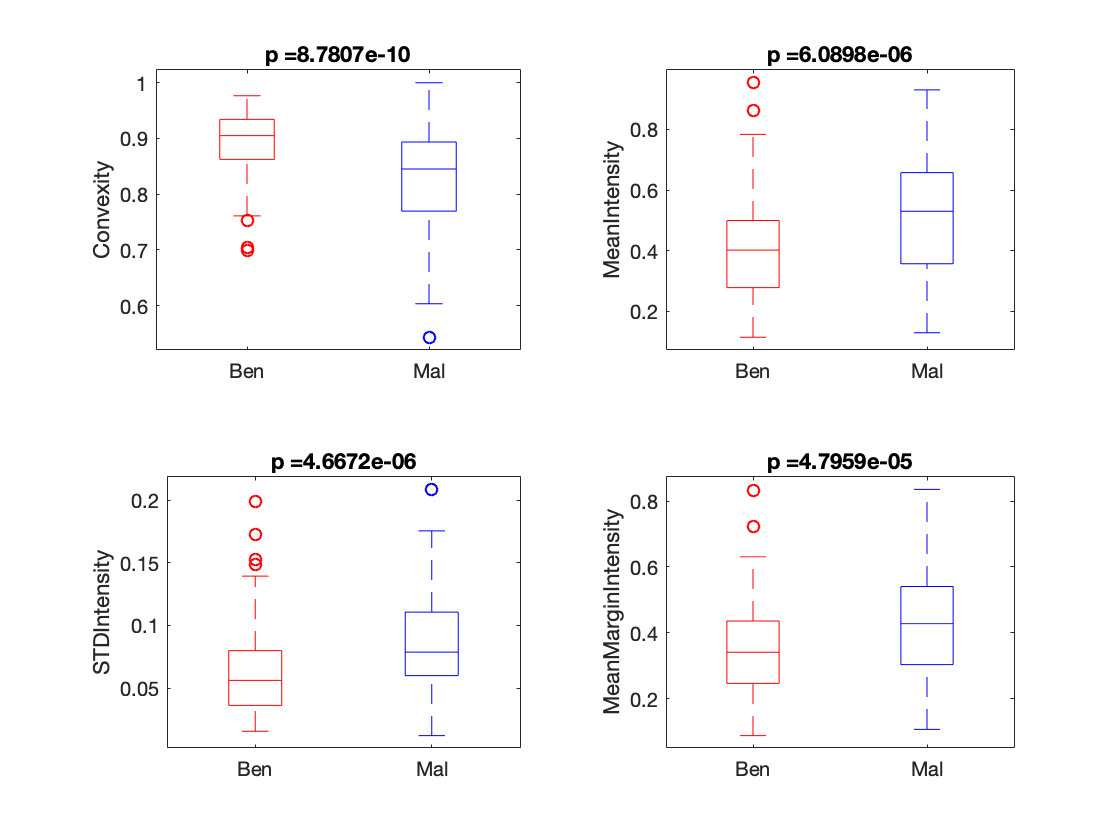

F_names=T1.Properties.VariableNames(1:numel(T1.Properties.VariableNames)-1);
F_sign=F_names(h==1);
p_sign=p(h==1);

L=ceil(sqrt(numel(F_sign))); 
figure
colors = 'rb';
for ip=1:numel(F_sign)
    subplot(L,L,ip)
    boxplot(T1{:,F_sign(ip)},T1.ClassLabel,'colors',colors,'symbol','o','Labels',{'Ben','Mal'});
    ylabel(F_sign(ip))
    title(strcat('p = ',num2str(p_sign(ip))))
end

We can specify the number of digits to display in `num2str`, e.g. 

`s = num2str(A,3)`

specifies that the maximum number of significant digits for floating-point values in A is 3.

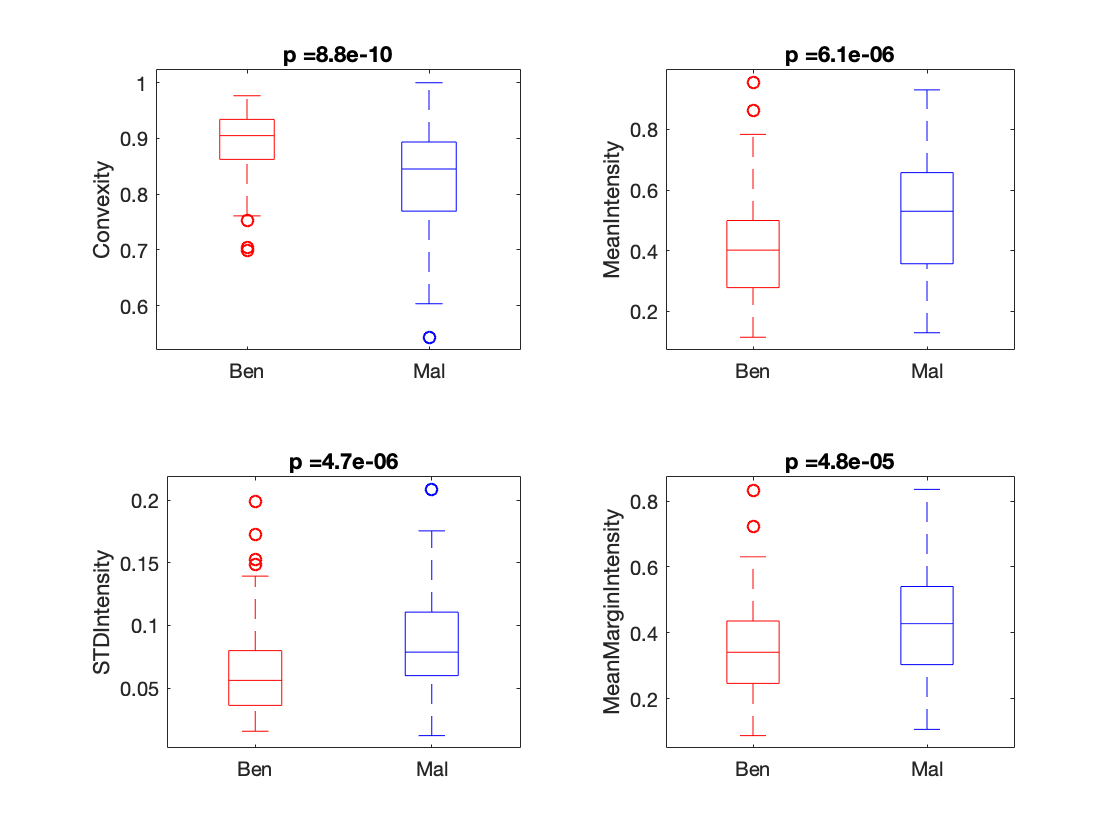

figure
colors = 'rb';
for ip=1:numel(F_sign)
    subplot(L,L,ip)
    boxplot(T1{:,F_sign(ip)},T1.ClassLabel,'colors',colors,'symbol','o','Labels',{'Ben','Mal'});
    ylabel(F_sign(ip))
    title(strcat('p = ',num2str(p_sign(ip),2)))
end